# Get Galaxy Profiles

## Stellar constats


c = 299792.458; % Speed of light in vacuum (Km/s)
% The positive charge RMS anomality of nucleons
B_sigma = 0.0000000061576779354155376441072376072967;

% The Star parameters
A_Sigma_star = 0.000000000000004495594326077030347123131497606; % The abnormality of Star


sig_stars = 0.945*15000;
sig_H = 103;
resolution=200;

% The Gas parameters
A_Sigma_H = 0.99e-10; % The electron-proton anomality of GAS

nloops = 14;


## Test of SPARC data

GalaxyName='NGC6015';


% NGC3198 NGC2841 NGC2955 NGC2403 NGC4389 UGC11914 NGC7793 UGC02487 NGC4013
% NGC6015 NGC6946 UGC02953 UGC09133



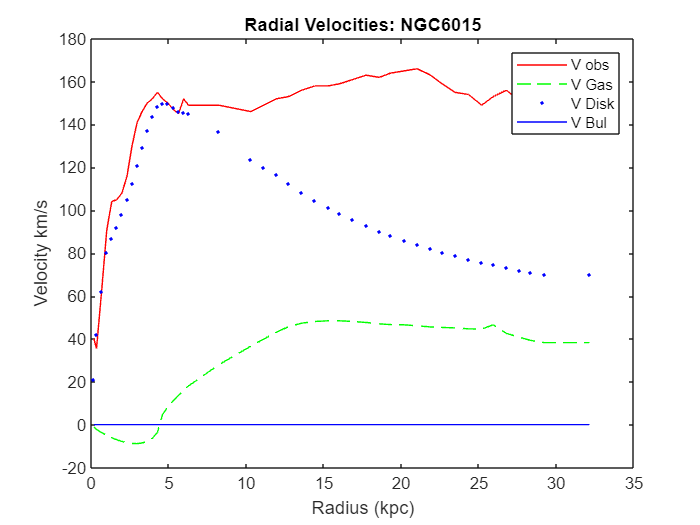


[profile,Mstar,MLgain] = compute_surface_density(GalaxyName, 'MassModels_Lelli2016c.txt', 'wise_ii.txt',1.00);

figure(1)
plot(profile(:,1), profile(:,4), 'r-')
hold on
plot(profile(:,1), profile(:,6), 'g--');
plot(profile(:,1), profile(:,7), 'b.');
plot(profile(:,1), profile(:,8), 'b-');
xlabel('Radius (kpc)'); ylabel('Velocity km/s');
legend('V obs', 'V Gas','V Disk','V Bul');
titles = append('Radial Velocities: ',GalaxyName);
title(titles);

hold off

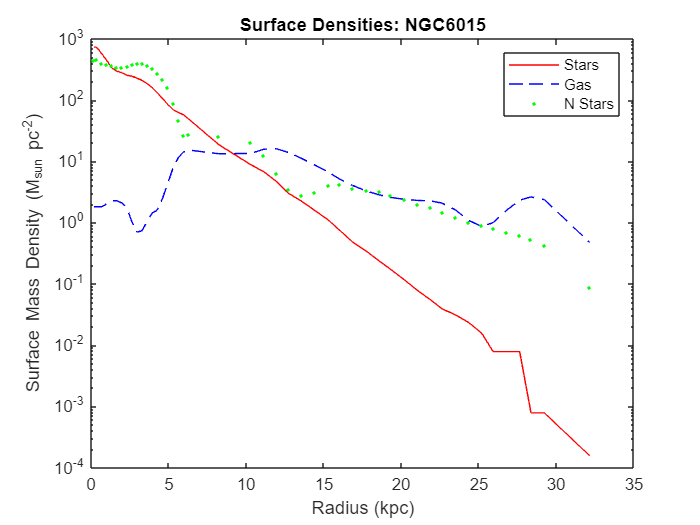


figure(2)
semilogy(profile(:,1), profile(:,2), 'r-')
hold on
semilogy(profile(:,1), profile(:,3), 'b--');
semilogy(profile(:,1), profile(:,11), 'g.');
xlabel('Radius (kpc)'); ylabel('Surface Mass Density (M_{sun} pc^{-2})');
legend('Stars', 'Gas','N Stars');
titles = append('Surface Densities: ',GalaxyName);
title(titles);

hold off

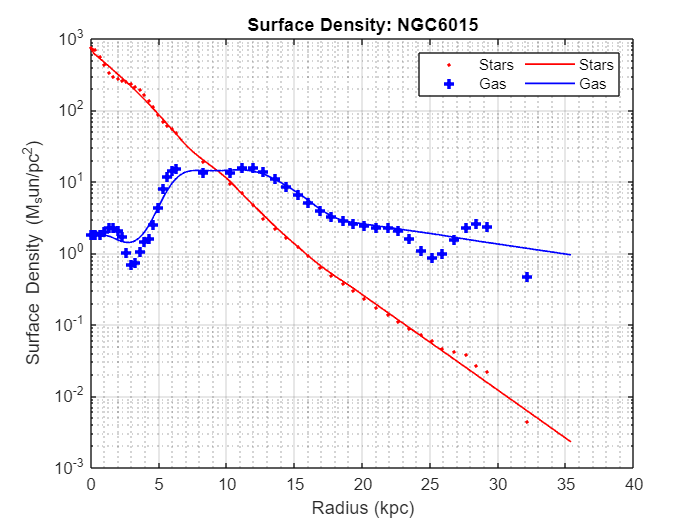

VelMassData = profile(:,[1,4,5,3,11]);
VelMassData(:,5) = (0.05*VelMassData(:,5) + 0.95*profile(:,2));

figure(3)
[r_data,V_obs,V_err,R_kpc,r_model,V_model,SigmaS,SigmaG,MStars,Mgas] = SRotation_curves(VelMassData,GalaxyName);

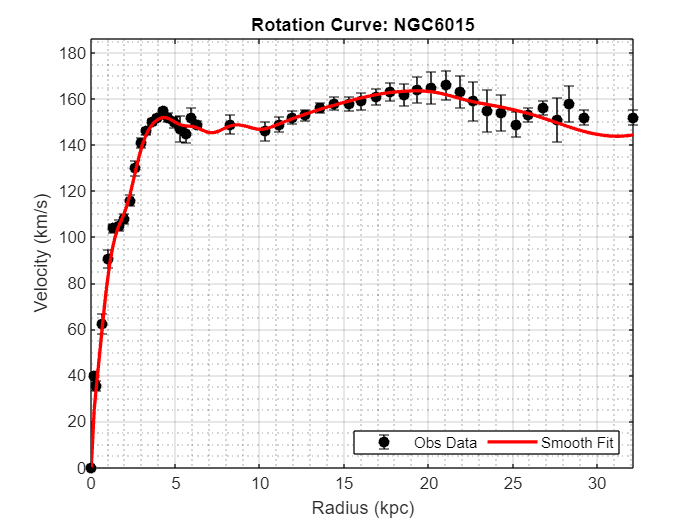


figure(4);
errorbar(r_data, V_obs, V_err, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Obs Data');
hold on;
plot(r_model, V_model, 'r-', 'LineWidth', 2, 'DisplayName', 'Smooth Fit');
xlabel('Radius (kpc)');
ylabel('Velocity (km/s)');
titles = append('Rotation Curve: ',GalaxyName);
title(titles);
legend('Location', 'southeast','NumColumns',2);
grid on;
grid minor;
xlim([0, max(R_kpc)]);
ylim([0, max(V_obs+3*V_err)]); % Enforce physical limits
hold off

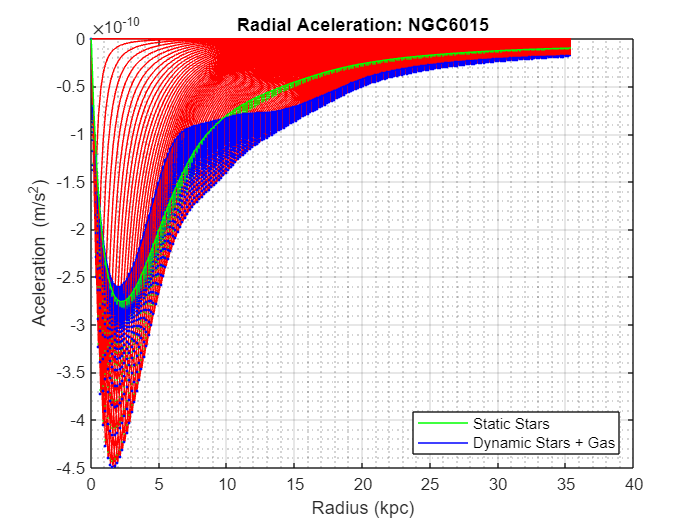

figure(5)
[V_tot,V_MOND,V_ele_G,V_ele,Zdist,StarProfile,GasZprofile,ax,ay] = fit_rotation_curveG(B_sigma,A_Sigma_star,A_Sigma_H,r_model,V_model,MStars,Mgas,sig_stars,sig_H,resolution,0,GalaxyName);

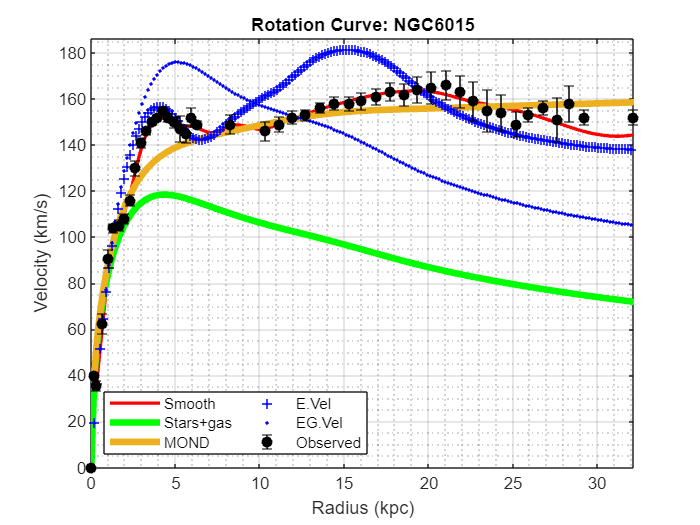

figure(6)
plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,V_ele,V_ele_G,GalaxyName);

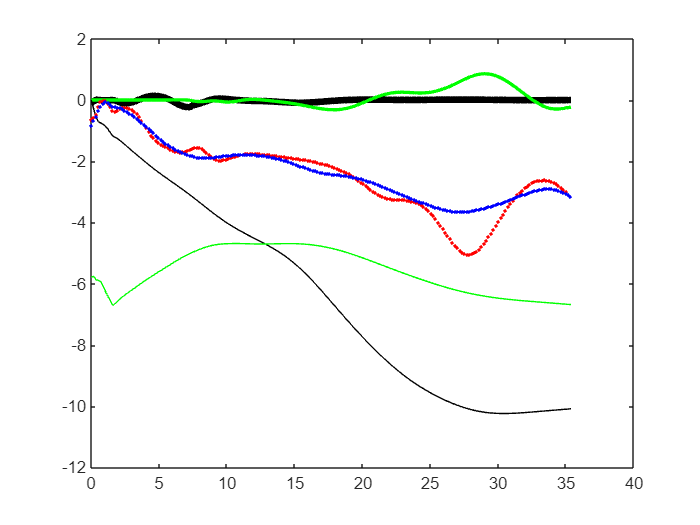

NSigma_S = MStars;
NSigma_H = Mgas;
NV_ele = V_ele;
testwhere=[];
for lps = 1:nloops
    ggain = 1.0-0.25*(mod(lps,3)>0) + 0.25*(mod(lps,3)==0);
    [Sigma_obs,Sigma_est,NSigma_S,NSigma_H,error,errorH,testwhere] = getNewDensities_v2(r_model,V_model,NV_ele,NSigma_S,NSigma_H,0.35,2.0*(lps>1),ggain,testwhere);

    figure(5)
    plot(r_model,5*error,"k-",'LineWidth', 4)
    hold on
    plot(r_model,5*errorH,"g-",'LineWidth', 2)
    plot(r_model,log(NSigma_S/max(NSigma_S)),"k-")
    plot(r_model,log(NSigma_H/max(NSigma_S)),"g-")
    plot(r_model,log(Sigma_obs/max(Sigma_obs)),"r.")
    plot(r_model,log(Sigma_est/max(Sigma_obs)),"b.")
    hold off

    figure(6)
    [V_tot,V_MOND,NV_ele_G,NV_ele,Zdist,StarProfile,GasZprofile,ax,ay] = fit_rotation_curveG(B_sigma,A_Sigma_star,A_Sigma_H,r_model,V_model,NSigma_S,NSigma_H,sig_stars,sig_H,resolution,lps,GalaxyName);

end

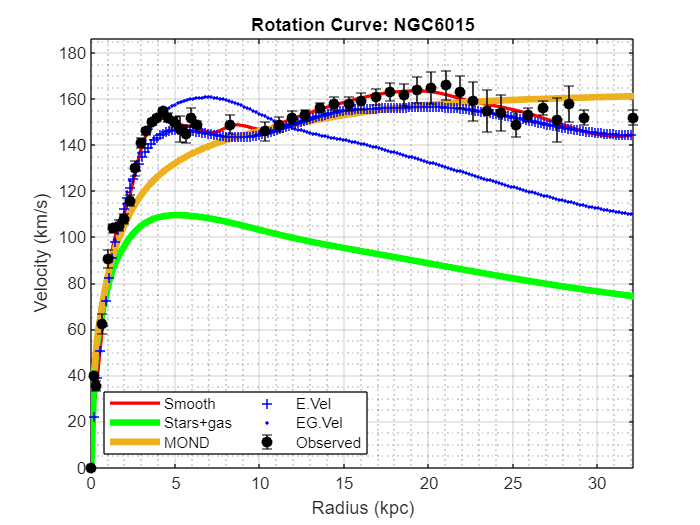

    figure(7)
    plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,NV_ele,NV_ele_G,GalaxyName);

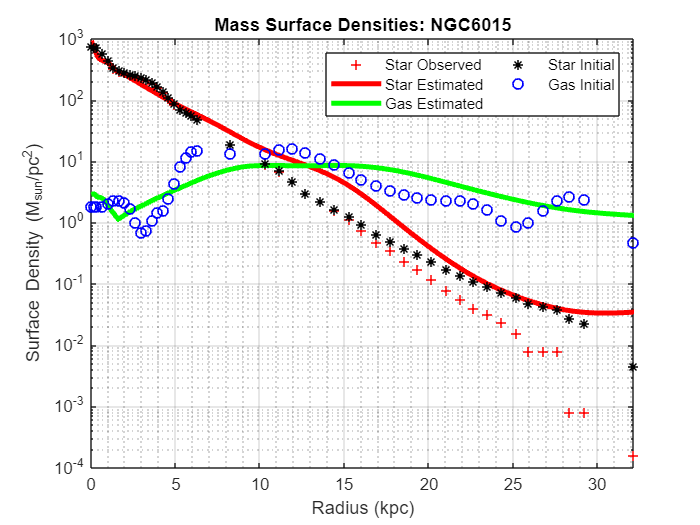

figure(7)
semilogy(profile(:,1),profile(:,2),"r+", 'LineWidth', 1, 'DisplayName', 'Star Observed')
hold on
semilogy(r_model,NSigma_S,"r-", 'LineWidth', 3, 'DisplayName', 'Star Estimated')
semilogy(r_model,NSigma_H,"g-", 'LineWidth', 3, 'DisplayName', 'Gas Estimated')
semilogy(R_kpc,SigmaS,"k*", 'LineWidth', 1, 'DisplayName', 'Star Initial')
semilogy(R_kpc,SigmaG,"bo", 'LineWidth', 1, 'DisplayName', 'Gas Initial')
xlabel('Radius (kpc)');
ylabel('Surface Density (M_{sun}/pc^2)');
titles = append('Mass Surface Densities: ',GalaxyName);
title(titles);
legend('Location', 'northeast','NumColumns',2);
xlim([0, max(r_data)]);
grid on;
grid minor;
hold off


mascts = (1000^2)*2*pi*(r_model(3)-r_model(2));
totmas = Mstar

totmas = 2.6546e+10

Rden = 1000*profile(:,1);
StarDen = profile(:,2);
integrand = 2 * pi * Rden .* StarDen;
totMassS = trapz(Rden, integrand)

totMassS = 2.4895e+10

StarDen = profile(:,11);
integrand = 2 * pi * Rden .* StarDen;
totMassS = trapz(Rden, integrand)

totMassS = 3.8423e+10

totEstMASS = mascts*sum(MStars.*r_model)

totEstMASS = 2.5148e+10

totEstMASS2 = mascts*sum(NSigma_S.*r_model)

totEstMASS2 = 2.7652e+10

totEstMASS2/totEstMASS

ans = 1.0996

totObsEstRatioGas= sum(NSigma_H.*r_model)/sum(Mgas.*r_model)

totObsEstRatioGas = 1.0201

save(append(GalaxyName,"103_200b.mat"));

## The estimated total mases

load(append(GalaxyName,"103_200b.mat"))
Rden = 1000*profile(:,1);
StarDen = profile(:,2);
integrand = 2 * pi * Rden .* StarDen;
totMassS = trapz(Rden, integrand);

StarDen = profile(:,11);
integrand = 2 * pi * Rden .* StarDen;
totMassS_2 = trapz(Rden, integrand);


GasDen = profile(:,3);
integrand = 2 * pi * Rden .* GasDen;
totMassG = trapz(Rden, integrand);

Rden = 1000*r_model;
integrand = 2 * pi * Rden .* NSigma_S;
totEstMASS_S = trapz(Rden, integrand);

integrand = 2 * pi * Rden .* NSigma_H;
totEstMASS_G = trapz(Rden, integrand);

totMas = [totMassS,totMassS_2,totMassG,totEstMASS_S,totEstMASS_G]

totMas = 1.0e+10 *

    2.4895    3.8423    1.3698    2.7651    1.4523


writematrix(totMas,append(GalaxyName,"103_200b.csv"))
fileID = fopen('galaxiesMass.csv','a');
nbytes = fprintf(fileID,'%s,%.5e,%.5e,%.5e,%.5e,%.5e\n',GalaxyName,totMas)

nbytes = 68

fclose(fileID)

ans = 0